% This script is for calculation of HEK 293T cell based ACh sensor FLIM
% imaging, starting from a analyzed stateYao data.

% In the end, the epoch based response is calculated and saved in 
% epoch_response_intensity_norm_all and epoch_response_lft_norm_all.

% data path from the server
datapaths = {"/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK001",...
    "/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK002",...
    "/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK003"}

datapaths = 1×3 cell array
    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK001"]}    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK002"]}    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK003"]}


% data path from icloud
datapaths = {"/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK002_tio",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK003_tio"}

datapaths = 1×3 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK002_tio"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK003_tio"]}


% This section is specific to each experiment.
% Write down the dataset analyzed, and the input for analyzing this dataset:
% the path to the dataset and analyzed stateYao data,
% the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
% which cycle positions we want to analyze
% how many acquisitions are used for either baseline start calculation or
% epoch based response calculation.

cd(datapaths{1})
load('analysis_offset0/20220914AChsensorHEK001_Analysis2022-09-23.mat')

drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

% This section is specific to each experiment.
% Write down the dataset analyzed, and the input for analyzing this dataset:
% the path to the dataset and analyzed stateYao data,
% the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
% which cycle positions we want to analyze
% how many acquisitions are used for either baseline start calculation or
% epoch based response calculation.

cd(datapaths{2})
load('analysis_offset0_ROI_adjustment/20220914AChsensorHEK002_Analysis2022-11-07.mat')

drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

% This section is specific to each experiment.
% Write down the dataset analyzed, and the input for analyzing this dataset:
% the path to the dataset and analyzed stateYao data,
% the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
% which cycle positions we want to analyze
% how many acquisitions are used for either baseline start calculation or
% epoch based response calculation.

cd(datapaths{3})
load('analysis_offset0/20220914AChsensorHEK003_Analysis2022-09-14.mat')

drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

% dose-dependent response of ACh sensor, 2022.11.21
cd /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220413_AchsensorHEK_001_dose
load('analysis_only_cycleposition1/20220413_AchsensorHEK_001_Analysis2022-09-09.mat')

all_epochs = [2 3 4 5 6 7 8 9 10 11 12 13];
drug_epochs = [2 3 4 5 6 7 8 9 10 11 12 13];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
drug_epoch_index = find(all_epochs == drug_epochs);
CyclePositions = [1]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

% dose-dependent response of ACh sensor, 2022.11.21
cd /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221104AchsensorHEK001_dose
load('analysis_offset0_roi_adjustment/20221104AchsensorHEK001_Analysis2022-11-07.mat')

all_epochs = [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23]; % all the epochs
drug_epochs = [2 4 6 8 10 12 14 16 18 20 22 23];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

drug_epoch_index = zeros(1,length(drug_epochs));
for i = 1:length(drug_epochs)
    drug_epoch_index(i) = find(all_epochs == drug_epochs(i));
end

CyclePositions = [1]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

stateYao.CyclePositions(:,2) = [];
stateYao.AcqTime(:,2) = []; % no cycle position 2

% dose-dependent response of ACh sensor, 2022.11.21
cd /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221104AchsensorHEK002_dose
load('analysis_offset0_ROI_adjustment5/20221104AchsensorHEK002_Analysis2022-11-07.mat')

all_epochs = [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23]; % all the epochs
drug_epochs = [2 4 6 8 10 12 14 16 18 20 22 23];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

drug_epoch_index = zeros(1,length(drug_epochs));
for i = 1:length(drug_epochs)
    drug_epoch_index(i) = find(all_epochs == drug_epochs(i));
end

CyclePositions = [1]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

% dose-dependent response of ACh sensor, 2022.11.21
cd /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221104AchsensorHEK002_dose
load('analysis_offset0_ROI_adjustment5/20221104AchsensorHEK002_Analysis2022-11-07.mat')

all_epochs = [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23]; % all the epochs
drug_epochs = [2 4 6 8 10 12 14 16 18 20 22 23];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

drug_epoch_index = zeros(1,length(drug_epochs));
for i = 1:length(drug_epochs)
    drug_epoch_index(i) = find(all_epochs == drug_epochs(i));
end

CyclePositions = [1]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

Matrix index is out of range for deletion.

% iAChSnFR response, 2022.11.21
cd /Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0801iAchHEK001/
load('Analysis_080921/0801iAchHEK001_Analysis2021-08-09.mat')

all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

drug_epoch_index = zeros(1,length(drug_epochs));
for i = 1:length(drug_epochs)
    drug_epoch_index(i) = find(all_epochs == drug_epochs(i));
end

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

% NE sensor, 2022.11.21
cd /Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0729NEsensorHEK001/
load('analysis_offset0/0729NEsensorHEK001_Analysis2022-11-09.mat')

all_epochs = [2 3 4 5]; % all the epochs
drug_epochs = [2 3 4 5];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

drug_epoch_index = zeros(1,length(drug_epochs));
for i = 1:length(drug_epochs)
    drug_epoch_index(i) = find(all_epochs == drug_epochs(i));
end

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

% dLIght sensor, 2022.11.21
cd("/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/DA sensor/0621dLightHEK001/")
load('analysis_0811/0621dLightHEK001_Analysis2021-08-11.mat')

all_epochs = [2 3 4 5]; % all the epochs
drug_epochs = [2 3 4 5];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

drug_epoch_index = zeros(1,length(drug_epochs));
for i = 1:length(drug_epochs)
    drug_epoch_index(i) = find(all_epochs == drug_epochs(i));
end

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

% revise the ROI selection based on StateYao
masks = stateYao.images.I_ROI_stack;
results = stateYao.Results;
Yao_GUI_ReviseROIsBasedOnCoordinates
masks2 = stateYao.images.I_ROI_stack;


% re-calculate the intensity and lifetime based on the new masks for the
% ROIs. 
% intensity_all and lifetime_all will include the raw intensity and
% lifetime values calculated from the new revised ROIs, from each cells of each cycle positions

intensity_all = {};
lifetime_all = {};

for i = 1:size(stateYao.AcqTime, 2) % cycle position number
    intensity = zeros(size(stateYao.ROI{i},1), size(stateYao.ROI{i}{1},2));
    lifetime = zeros(size(stateYao.ROI{i},1), size(stateYao.ROI{i}{1},2));
    for j = 1:size(stateYao.ROI{i}{1},2) % roi number
        for k = 1:size(stateYao.ROI{i},1) % acq number
            rgbLifetimes = stateYao.images.origData.rgbLifetimes{i}(:,:,:,k);
            lifetimeMaps = stateYao.images.origData.lifetimeMaps{i}(:,:,k);
            projects = stateYao.images.origData.projects{i}(:,:,k);

            try
                orig_mask1 = logical(masks{i}{k}(:,:,j));
                orig_mask2 = logical(masks2{i}{k}(:,:,j));
                intensity(k, j) = Yao_calc_Projection(projects, orig_mask2);
                lifetime(k, j) = Yao_calc_Lifetime(projects, lifetimeMaps, orig_mask2);
            catch
                warning(['cycle ', num2str(i), ' , cell ', num2str(j), ' , acq ', num2str(k), ' is epmty'])
            end

            
        end
    end

    intensity_all{i} = intensity;
    lifetime_all{i} = lifetime;
end

% This is an old script used for extracting the experimental information
% from the Excel files, including the epoch change acquisitions for each
% cycleposition.

FLIM_posthoc_analysis_dendrite_HEK_cell


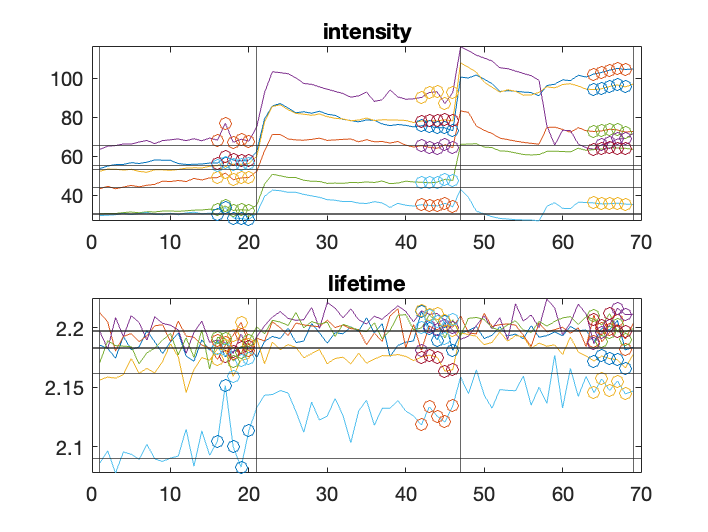

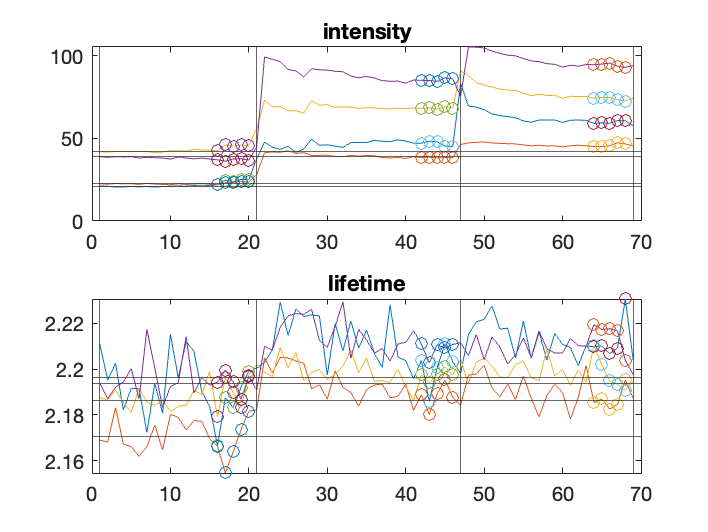

% This section is used for calculation of epoch based response.
% baseline response = baseline_epoch_response - baseline_start;
% other epoch response = epoch_response - baseline_epoch_response;

% calculated response will be included in cell
% epoch_response_intensity_norm_all and cell
% epoch_response_lft_norm_all. Each cell correspond to each cycle
% position.

epoch_response_intensity_norm_all = {};
epoch_response_lft_norm_all = {};

for i_cycle = 1:length(CyclePositions)

    % the intensity and lifetime raw data
    intensity = intensity_all{CyclePositions(i_cycle)};
    lft = lifetime_all{CyclePositions(i_cycle)};

    % the epoch transition points
    eval(['EpochStartAcq = EpochStartAcq', num2str(CyclePositions(i_cycle)), ';'])


    % pre-define the epoch response and baseline start
    epoch_response_intensity = zeros(length(drug_epochs)-1,size(intensity, 2));
    epoch_response_lft = zeros(length(drug_epochs)-1,size(lft,2));
    baseline_start_intensity = zeros(1, size(intensity,2));
    baseline_start_lft = zeros(1, size(lft,2));
    
    % the epoch transition index in the raw data of intensity and lft
    drug_epoch_start_acq = EpochStartAcq(all_epochs-1);
    eval(['drug_epoch_start_acq_',num2str(CyclePositions(i_cycle)), '=drug_epoch_start_acq(drug_epoch_index);'])

    
    % calculation of baseline start (mean of the first x acqs)
    for i = 1:size(intensity, 2)
        baseline_start_intensity(i) = mean(intensity(drug_epoch_start_acq(1):drug_epoch_start_acq(1)+baseline_acq_num-1, i));
        baseline_start_lft(i) = mean(lft(drug_epoch_start_acq(1):drug_epoch_start_acq(1)+baseline_acq_num-1, i));
    end
    

    % calculation epoch based response (mean of last x acqs)
    figure;
    subplot(2,1,1);
    plot(intensity)
    yline(baseline_start_intensity)
    xline(drug_epoch_start_acq(drug_epoch_index))
    title('intensity')
    hold on

    for i = 1:size(intensity, 2)
        for j = 1:length(drug_epochs)-1
        epoch_response_intensity(j,i) = mean(intensity((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1),i));
        scatter((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1), intensity((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1),i))
        hold on
        end
    end

    hold off

    subplot(2,1,2);
    plot(lft)
%     ylim([3.8 4.15])
    yline(baseline_start_lft)
    xline(drug_epoch_start_acq(drug_epoch_index))
    title('lifetime')
    hold on

    for i = 1:size(intensity, 2)
        for j = 1:length(drug_epochs)-1
        epoch_response_lft(j,i) = mean(lft((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1),i));
        scatter((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1), lft((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1),i))
        hold on
        end
    end
    hold off

    saveas(gcf, ['cycle ', num2str(i_cycle),'.fig'])
    saveas(gcf, ['cycle ', num2str(i_cycle),'.png'])
    
    
    epoch_response_intensity_norm = zeros(length(drug_epochs)-1,size(intensity, 2));
    epoch_response_lft_norm = zeros(length(drug_epochs)-1,size(lft,2));
    
    % first raw: baseline change, baseline response - baseline start
    epoch_response_intensity_norm(1,:) = (epoch_response_intensity(1,:) - baseline_start_intensity)./baseline_start_intensity;
    epoch_response_lft_norm(1,:) = epoch_response_lft(1,:) - baseline_start_lft;

    % normalized epoch response. intensity: df/f0; lifetime: minus baseline response
    epoch_response_intensity_norm(2:end,:) = (epoch_response_intensity(2:end,:) - epoch_response_intensity(1,:))./epoch_response_intensity(1,:);
    epoch_response_lft_norm(2:end,:) = epoch_response_lft(2:end,:) - epoch_response_lft(1,:);
    

    epoch_response_intensity_norm_all{CyclePositions(i_cycle)} = epoch_response_intensity_norm;
    epoch_response_lft_norm_all{CyclePositions(i_cycle)} = epoch_response_lft_norm;

end

% calc EC50 if needed
intensity_response_EC50 = zeros(length(drug_epochs)-1,length(baseline_start_intensity));
lft_response_EC50 = zeros(length(drug_epochs)-1,length(baseline_start_intensity));
for i = 1:length(baseline_start_intensity)
    baseline_intensity = baseline_start_intensity(1,i);
    max_response_intensity = max(epoch_response_intensity(:,i));
    intensity_response_EC50(:,i) = (epoch_response_intensity(:,i) - baseline_intensity)/(max_response_intensity - baseline_intensity);
    
    baseline_lft = baseline_start_lft(1,i);
    max_response_lft = max(epoch_response_lft(:,i));
    lft_response_EC50(:,i) = (epoch_response_lft(:,i) - baseline_lft)/(max_response_lft - baseline_lft);
end


After this analysis, the data in epoch_response_intensity_norm_all and epoch_response_lft_norm_all is copied and pasted in Prism.

Next section is to generate the summary trace from 20220914AChsensorHEK003_tio


intensity1_normarlized = (intensity1 - min(intensity1))./range(intensity1);
intensity2_normarlized = (intensity2 - min(intensity2))./range(intensity2);
lft1_normarlized = (lft1 - min(lft1))./range(lft1);
lft2_normarlized = (lft2 - min(lft1))./range(lft2);


difference = zeros(1,135);

for i = 1:135
    difference(i) = intensity_all{1,1}(i,1) - stateYao.Results.spc_calculateROIvals.Projection{1,1}{i}(1);
end

sum(difference)

ans = 0

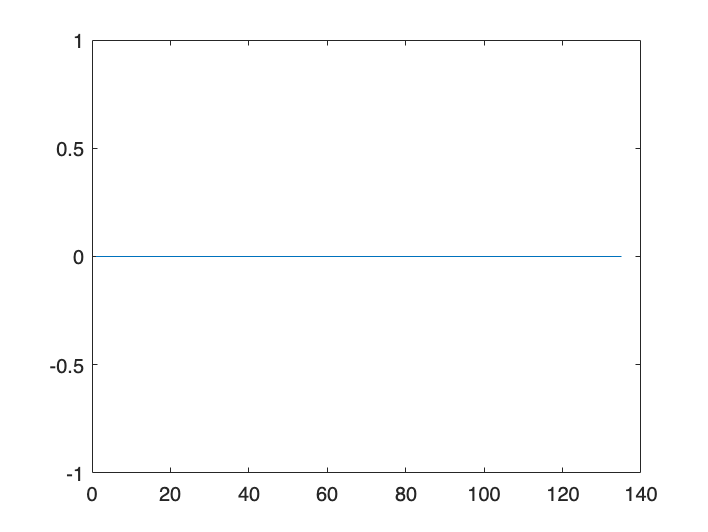

figure
plot(difference)